clear all;

%importa pontos experimentais
filename = 'Dados/pontos2.txt'; % Replace with your file name
delimiterIn = '\n'; % Specify the delimiter (e.g., space, comma, tab)
headerlinesIn = 0; % Number of header lines to skip (if any)

data = importdata(filename, delimiterIn, headerlinesIn);
data = flip(data);

time = linspace(0,19.98,999);
points = linspace(0,999,999);

P1 = data(692);
P2 = data(732);

T = (732-692) * 0.02;

delta = log(P1/P2);
lambda = delta / T;

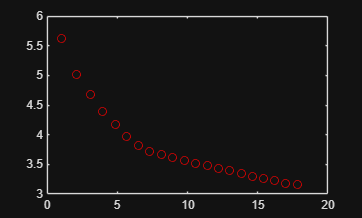

% y = pi + A*exp(-b*t)
% ln(y-pi) = ln(A*exp(-b*t)
% ln(y-pi) = ln(A) + ln(exp(-b*t)) = ln(A) + (-b*t)*ln(e) = ln(A) -b*t
[pks, pksloc] = findpeaks(data, time);
plot(pksloc, pks, "ro")

x1 = pksloc;
y1 = log(pks - pi);
A = [ones(numel(x1),1),x1(:)];
% coeffs = lsqlin(A,y1(:),-A,-y1(:),[],[],[],[],[],optimset('algorithm','active-set','display','off'));
coeffs = A \ y1(:);
lnA = coeffs(1);
negb = coeffs(2);
lambda = -negb

lambda = 0.2353

exp_decay = zeros(size(data));
i = 1;
for t = time
    exp_decay(i) = pi + exp(lnA)*exp(negb * t);
    i = i+1;
end

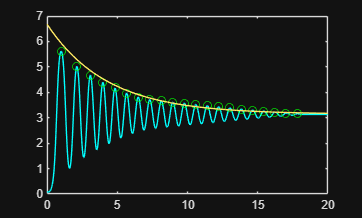

plot(time, data, Color="cyan");
hold on;
plot(pksloc,pks, "go");
plot(time, exp_decay)

save("..\Parametros\lambda.mat", "lambda");